## TOPIC 4: Loops and logic

ENGR105, 9/15/20

### Introductory remarks

We have accomplished a lot so far -- we've created arrays of varying sizes, manipulated the entries in these arrays through indexing and array mathematics, and learned how to package collections of code into functions. 

We've worked a lot with **vectors**, in particular. We have created *row* or *column* vectors through explicitly defining entries, using slice/colon (`:`) notation to create vectors with a defined increment size between entry values, using `linspace()` to create vectors with a defined number of increments, and so forth.

% Explicitly define a vector
a = [5,3,2,6,2,1]

a =      5     3     2     6     2     1


% Create a vector with entries starting at 1 and incrementing by 2 until 9
b = 1:2:9

b =      1     3     5     7     9


% Create a vector consisting of 5 evenly spaced values between (and
% including) 1 and 8;
c = linspace(1,8,5)

c =     1.0000    2.7500    4.5000    6.2500    8.0000


#### Example - Fibonacci sequence

The above methods are very efficient and should be used when possible. However, in other cases we may wish to create vectors with entries defined by *more sophisticated patterns*. For example, consider the Fibonacci sequence, an infinite sequence defined by the following rules, that you may recall from previous math classes or popular culture.

                
$$\begin{array}{l}
\textrm{𝑥}\left(1\right)=0\\
\textrm{𝑥}\left(2\right)=1\\
\textrm{𝑥}\left(3\right)=\textrm{𝑥}\left(2\right)+\textrm{𝑥}\left(1\right)\\
\vdots \\
\textrm{𝑥}\left(\textrm{𝑛}\right)=\textrm{𝑥}\left(\textrm{𝑛}-1\right)+\textrm{𝑥}\left(\textrm{𝑛}-2\right)
\end{array}$$


Using what we've learned so far, **create a vector **`x`** containing the first 10 elements of the Fibonacci sequence**.

% The first two entries are explicitly defined
x(1) = 0;
x(2) = 1;
% The next eight entries must be calculated individually based upon the
% previous two values
x(3) = x(1) + x(2);
x(4) = x(2) + x(3);
x(5) = x(3) + x(4);
x(6) = x(4) + x(5);
x(7) = x(5) + x(6);
x(8) = x(6) + x(7);
x(9) = x(7) + x(8);
x(10) = x(8) + x(9);
disp(x)

     0
     1
     1
     2
     3
     5
     8
    13
    21
    34



Or alternatively, by doing the math "in your head" and explicitly defining a vector:

% Explicitly define a fibonacci vector, x
x = [0,1,1,2,3,5,8,13,21,34]

x =      0     1     1     2     3     5     8    13    21    34


In both cases, this process was extremely tedious and impractical for creating larger vectors or those with more complicated rules.

**Note**: always proofread your code before running (and submitting an assignment!). Just like when writing a paper, it is easy to make "typos" that could dramatically affect the output of your code.

### FOR loops

Fortunately, loops allow us to more easily repeat statements, repeatedly invoke functions, or manipulate multidimensional data. The first type of loop we will discuss is a `for` loop, which enable us to repeat tasks **for** a **fixed number of iterations**. A `for` loop has the following form:

% Iterate for k equaling each value in the row vector
% [1,2,3,4,5,6,7,8,9,10]
for k = 1:10
    % For each iteration of the for loop, display the value of the index,
    % k, squared.
    disp(k^2)
end

     1

     4

     9

    16

    25

    36

    49

    64

    81

   100



#### Anatomy of a `for` loop

- The `for` command indicates that the statements to follow should be repeated

- The variable `index` is the loop counter that sequentially takes the values contained in a row vector `<values>`.

- Any number of **statements** (i.e. productive code) may be contained within the loop and will be executed each time the `for` loop iterates. **The statement operations often depend on the index**, k.

- The `end` statement returns control to `for` until `index` has iterated through all entries in the `<values>` vector.

**Note**: we indent the contents of the for loop for ease of visualization.

The procedure that occurs when a for loop is called may also be explained visually:

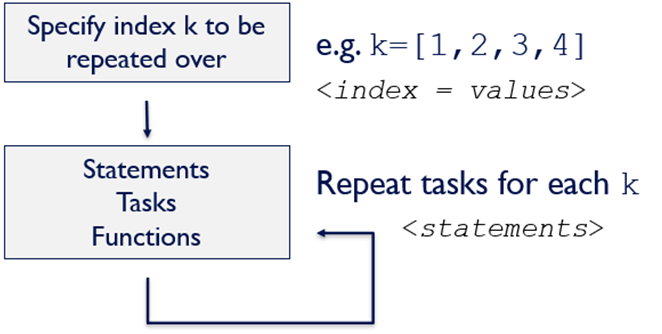

In other words, for loops are used when the number of repeats are known a priori.

**Note**: There is nothing special about the row vector `<values>` - it may be created in any of the ways we have discussed so far. The most common scenario involves iterating from index 1 by 1 to some end value by specifiying the colon (`:`) operator.

**The following are examples of using for loops to**** create a new vector****.**

**1) Defining entries***** by the index of the for loop*****.**

% jj takes the values of 1 in the first iteration, 2 in the second
% iteration, etc.
for jj = 1:5
    % The value of the computation 2*jj is stored in the jj-th location of
    % vector v, which grows during each iteration of the for loop
    v(jj) = 2*jj
end

v = 2

v =      2     4


v =      2     4     6


v =      2     4     6     8


v =      2     4     6     8    10


disp(v)

     2     4     6     8    10



**Note**: The above example is simply a more compact way of doing the vector operations that we have already mastered.

**2) Indexing a generalized vector using a **`for`** loop and **`length().`

General vectors may be fully parsed by creating a loop counter based on the length of the vector

% An arbitrary vector
v0 = [5, -2, 4, 1];
for jj = 1:length(v0)
    % In the jj-th position of v1, store the value at the jj-th position of
    % v0 multiplied by 2.
   v1(jj) = 2*v0(jj) 
end

v1 = 10

v1 =     10    -4


v1 =     10    -4     8


v1 =     10    -4     8     2


disp(v0)

     5    -2     4     1



disp(v1)

    10    -4     8     2



In the above case, `length(v0)` is equivalent to 4.

**3) Growing vectors using a **`for`** loop and **`end+1`** assignments**

Recall vector operations using `end`:

v = 1:4;
% Return the last element of v
v(end)

ans = 4

v(end+1) = 1

v =      1     2     3     4     1


The above approach may be used to sequentially populate an initially empty vector.

v = [];
%Vector v is initialized as an empty set and is grown by adding to its
%end-ith + 1 index within the for loop
for jj = 1:.1:2
    %jj takes the values of 1 in the first iteration, 1.1 in the second
    %iteration, 1.2 in the third iteration, etc. – note that non-integer
    %values cannot be used to index a vector
    v(end+1) = 2*jj
end

v = 2

v =     2.0000    2.2000


v =     2.0000    2.2000    2.4000


v =     2.0000    2.2000    2.4000    2.6000


v =     2.0000    2.2000    2.4000    2.6000    2.8000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


v

v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


Note: non-integes values cannot be used to index a vector. Also, this examaple is for visualizing the `for` loop. A general rule-of-thumb is to use vectorization when possible. For example, the above output could be generated from **one line of code:**

v = 2*(1:.1:2)

v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


**4) Indexing vectors using a **`for`** loop and incrementing counter.**

In this alternate formulation, a counter is initialized/incremented in lieu of adding to the end + 1 index of vector `v`

n = 0;
% n is a counter the increments by 1 in every iteration of the for loop and
% identifies the vector index into which jj is placed
for jj = 1:.1:2
    %n is incremented by 1 in each iteration of the loop
    n = n+1; %counter
    v(n) = 2*jj
end

v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


v

v =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000


#### Additional (pecular) notes

Recall that the vector to be looped through (`<values>` above) is a row vector. Technically index will take on every column entity in the `<values>` array. 

- If `<values>` is a **column vector**, the loop will perform once and index will take on the entire column vector

%For the values it must take in a row verctor 
for jj = (1:5)'
    jj
end

jj =      1
     2
     3
     4
     5


Compared to the "normal case" of `<values>` being a row vector:

for jj = (1:5)
    jj
end

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

- If `<values>` is a matrix, the loop will iterate according to the number of columns and index will take on each column of the matrix as a column vector.

M = [5, 3; 1, 9]

M =      5     3
     1     9


for jj = M
    jj
end

jj =      5
     1


jj =      3
     9


- If `<values>` is a matrix, and you want index to take on all entries of the matrix, you could use the unwinding command (`:`) mentioned previously. In this case, `M` is unwrapped and transposed to yield a row vector.

for jj = M(:)'
    jj
end

jj = 5

jj = 1

jj = 3

jj = 9

#### Nested `for` loops

Multiple `for` loops may used such that one for loop is run *inside* of another for loop, yielding *nested *`for`* loops*. In the following example, the "inside" `for` loop runs to completion for each loop of the "outside" `for` loop.

v = [];
p = [];
for jj = 1:3
    for kk = 1:3
        v(end+1) = jj;
        p(end+1) = kk;
    end
end





disp(v)

     1     1     1     2     2     2     3     3     3



disp(p)

     1     2     3     1     2     3     1     2     3



In the above case, the nested `for` loop circulates 3 times before passing back to the next iteration of the higher level `for` loop.

**Note**: we indent the contents of each `for` loop for ease of visualization.

#### Example - back to the Fibonacci sequence

Previously, we wanted to create a vector containing the first 10 elements of the Fibonacci sequence.

                
$$\begin{array}{l}
\textrm{𝑥}\left(1\right)=0\\
\textrm{𝑥}\left(2\right)=1\\
\textrm{𝑥}\left(3\right)=\textrm{𝑥}\left(2\right)+\textrm{𝑥}\left(1\right)\\
\vdots \\
\textrm{𝑥}\left(\textrm{𝑛}\right)=\textrm{𝑥}\left(\textrm{𝑛}-1\right)+\textrm{𝑥}\left(\textrm{𝑛}-2\right)
\end{array}$$


This can be done much more efficiently using a `for` loop.

% Populate an array containing the first ten numbers of the sequence.
n = 10;
% Empty the vector x - we used it previously
x = [];
x(1) = 0;
x(2) = 1;
% Create each subsequent entry by taking the sum of the previous two
% entries
for k = 3:n
    x(k) = x(k-1) + x(k-2);
end


% Display the vector
disp(x)

     0     1     1     2     3     5     8    13    21    34



**Question: what if we want to display all numbers in the Fibonacci sequence that are less than 100?** This is tedious because we do not know beforehand how many entries that corresponds to.

**Takeaway**: `for` loop are good when you know the number of iterations to perform. `while` loops are better when you do not know the number of repeats a priori.

### WHILE loops

`while` loops are a type of iteration in which a sequence of instructions may be repeated as long as some condition is true. To understand `while` loops, we first need to discuss *relational and logic operators* in MATLAB.

In both cases, `true` is equivalent to `1` and `false` is equivalent to `0`.

#### Relational operators

Relational operators compare values (or vectors, matrices, arrays) and yield a `true` (`1`) or `false` (`0`) result.

#### 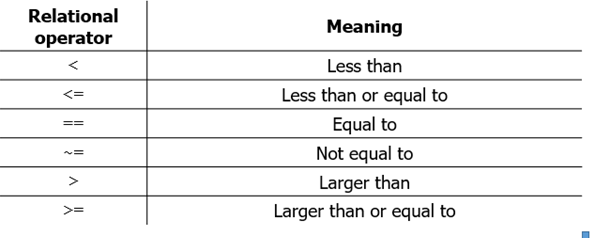

% Examples
3>4;
3<4;
3<= 0;
3<3;






#### Logical operators

Logical operators are commands that yield a `true` (`1`) or `false` (`0`) result.

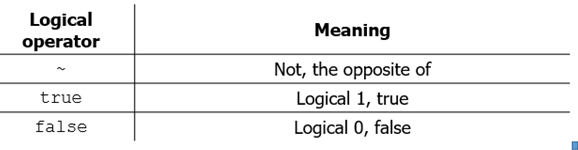

true

ans = logical
   1


~true

ans = logical
   0


true == ~false

ans = logical
   1


#### Examples

The logical state (`true` or `false`) can be stored in a variable, just as one stores a number.

% Logical statement examples



% Relational operators can also operate on variables




The `true`/`false` output may also be incorporated into mathematical expressions.

s = true>false

s = logical
   1


b = true + true

b = 2

c = 5 + (2==2)*5

c = 10

#### Anatomy of a `while` loop

`while` loops take the following form:

ind = 1;
% ind is incremented within the loop and terminates the while loop after 4
% iterations, when ind < 5 is no longer true.
while ind<5
    % The incremetnation of ind is not suppressed with a semicolon so that
    % you can see the line of code that are run in each iteration.
    ind = ind+1
end

ind = 2

ind = 3

ind = 4

ind = 5

- The `while` continues execution of the loop **as long as its **`<logical statement> `**evaluates to **`true.`

- the `<logical statement>` can be any set of numbers, relational operators, commands, or even functions that yield a logical output. 

- Usually the `<logical statement>` is dependent upon the state of some variable that is modified in the `<statements> `within the loop.

- As with a `for` loop, any number of `<statements>` may be contained within the loop and will be executed each time the `while `loop iterates.

- The `end` statement returns control to `while` as long as `<logical statement>` is true.

- **Warning**: **if **`<logical statement>` **is always true, than your code will become an infinite loop!** And MATLAB might crash.

The procedure that occurs when a `while` loop is called may also be explained visually:

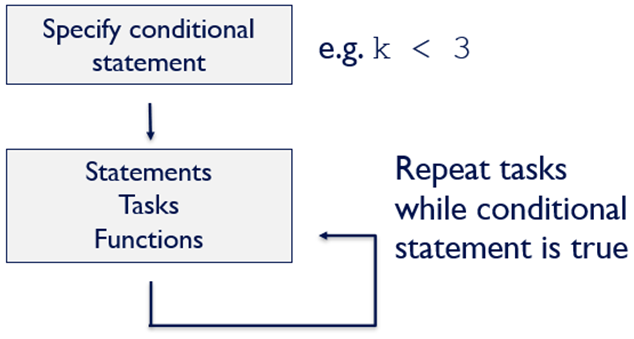

#### Example: simulating the roll of two dice

The following code is an example of simulation to observe the number of rolls until two dice are rolled with the same value.

% Variable to store the number of rolls until the same dice reading is
% observed
r2s = 0; 
% Initialize while loop logical. As long as contRoll is true, we will
% "continue rolling"









#### Example: back again to the Fibonacci sequence

Previously, we wanted to create a vector containing all elements of the Fibonacci sequence less than 100.

                
$$\begin{array}{l}
\textrm{𝑥}\left(1\right)=0\\
\textrm{𝑥}\left(2\right)=1\\
\textrm{𝑥}\left(3\right)=\textrm{𝑥}\left(2\right)+\textrm{𝑥}\left(1\right)\\
\vdots \\
\textrm{𝑥}\left(\textrm{𝑛}\right)=\textrm{𝑥}\left(\textrm{𝑛}-1\right)+\textrm{𝑥}\left(\textrm{𝑛}-2\right)
\end{array}$$


This can be done much more efficiently using a `while` loop.

% Max value of entries in Fibonacci sequence
n = 100;
% Define first two entries
x(1) = 0;
x(2) = 1;
% Iterate as long as the last element is less than 100.







**Note**: why do we remove the last element in this example? We remove it because the loop ends when the last element of the vector is greater than 100. Since we do not want *any* of the vector elements to be greater than 100, we must remove the last entry.

#### Vector preallocation

Preallocation is the process of creating a data structure (e.g. a vector) of final size (usually padded with zeros) before modifying the contents. This reduces the computational time by eliminating the operations associated with resizing the array. 

**Preallocation is a best practice to use whenever possible -- it is important if you use a **`for`** loop to populate a vector.**

Consider the Fibonacci sequence example using the `for` loop, in which we populated a vector with the first 10 entries of the Fibonacci sequence.

Let's calculate the time required to produce this Fibonacci vector of *differing lengths, with* and *without* preallocation.

To perform this analysis, we are going to:

- For sequence length, we will determine the time required to calculate the Fibonacci sequence, with and without preallocation

- Repeat with a greater number of Fibonacci elements.

- Plot *sequence (vector) length* vs. *computation time*.

% Define vector containing the number of entries in each successive
% Fibonacci vector.
N = round(logspace(0,8,20))

N =            1           3           7          18          48         127         336         886        2336        6158       16238       42813      112884      297635      784760     2069138     5455595    14384499    37926902   100000000


% Preallocate vectors to store time information
t_no = zeros(1,length(N));
t_yes = zeros(1,length(N));

% Calculate the time for each vector of length N(m)
for m = 1:length(N)
    
    % Calculate Fibonacci sequence vector without preallocation
    x = [];
    tic
    % Define first two entries
    x(1) = 0;
    x(2) = 1;
    % Create each subsequent entry by taking the sum of the previous two
    % entries
    for k = 3:N(m)
    	x(k) = x(k-1) + x(k-2);
    end
    t_no(m) = toc;
    
    % Calculate Fibonacci sequence vector with preallocation
    tic;
    x = zeros(1,N(m));
    % Define first two entries
    x(1) = 0;
    x(2) = 1;
    % Create each subsequent entry by taking the sum of the previous two
    % entries
    for k = 3:N(m)
    	x(k) = x(k-1) + x(k-2);
    end
    t_yes(m) = toc;
end

Plotting the above simulation results. Note the addtions to the code to produce a more professional plot. We will discuss plotting in detail later in the semester.

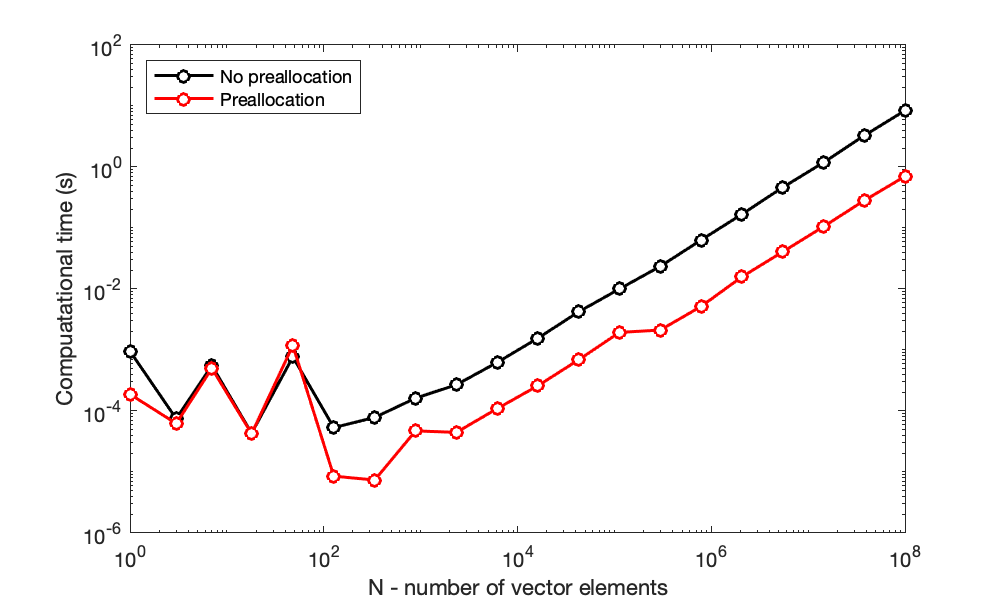

% Define dimensions of plot
figure('Position',[0,0,500,300]);
% Plot the functions
plot(N,t_no,'ko-',N,t_yes,'ro-','LineWidth',1.5,'MarkerFaceColor','auto')
% Graphical parameters
set(gca, 'XScale', 'log')   % "log" axes - x
set(gca, 'YScale', 'log')   % "log" axes - y
set(gca,'XMinorTick','on')
xlim([10^0,10^8]);  % range of x values on plot
ylim([10^-6,10^2]); % range of y values on plot
xlabel('N - number of vector elements');
ylabel('Compuatational time (s)');
legend('No preallocation','Preallocation','Location','northwest')

**Major takeaway**: you can save an **order of magnitude** of computational time using **preallocation**. 

#### For loops vs. vectorization

As described above, loops can be very useful for repeating many tasks a known or unknown number of times. In the case of for loops, we performed examples that could also be accomplished with vectorization, *i.e.* operating on a vector. Which of these approaches is better? To evaluate this, let's compare the computational time for each.

Specifically, let's calculate `b(k) = a(k)*a(k)`, where `a` is some vector. That is, we want to create a vector `b` in which each entry in the vector is the square of the corresponding entry in the vector `a`.

**1) Using a **`for`** loop.**

**2) Vectorization (e.g. using an element-wise operation)**

To perform this analysis, we are going to:

- Create a vector of a known length.

- Calculate the time required to perform the above operation on that vector using either a for loop or with vectorization.

- Repeat with a longer vector.

- Plot *vector length* vs. *computation time*.

% Define vector containing number of entries in potential vector.
N = round(logspace(0,8,20))

N =            1           3           7          18          48         127         336         886        2336        6158       16238       42813      112884      297635      784760     2069138     5455595    14384499    37926902   100000000


% Preallocate vectors to store information
t_for = zeros(1,length(N));
t_vec = zeros(1,length(N));

% Calculate the time for each vector of length N(m)
for m = 1:length(N)
    % Create vector of random numbers with dimension 1xN(m)
    a = rand(1,N(m));
    
    % Calculate time for for loop
    tic
    % Preallocate for loop vector
    b_for = zeros(1,N(m));
    % Calculate each entry in b by looping through all of vector a
    for n = 1:N(m)
        b_for(n) = a(n)^2;
    end
    t_for(m) = toc;
    
    % Calculate time for vectorization
    tic
    % Calculate all entries in b by element-wise exponentiation
    b_vec = a.^2;
    t_vec(m) = toc;
    
    % Clear b vectors for next iteration
    clear b_for b_vec
end

Plotting the above simulation results. Note the addtions to the code to produce a more professional plot. We will discuss plotting in detail later in the semester.

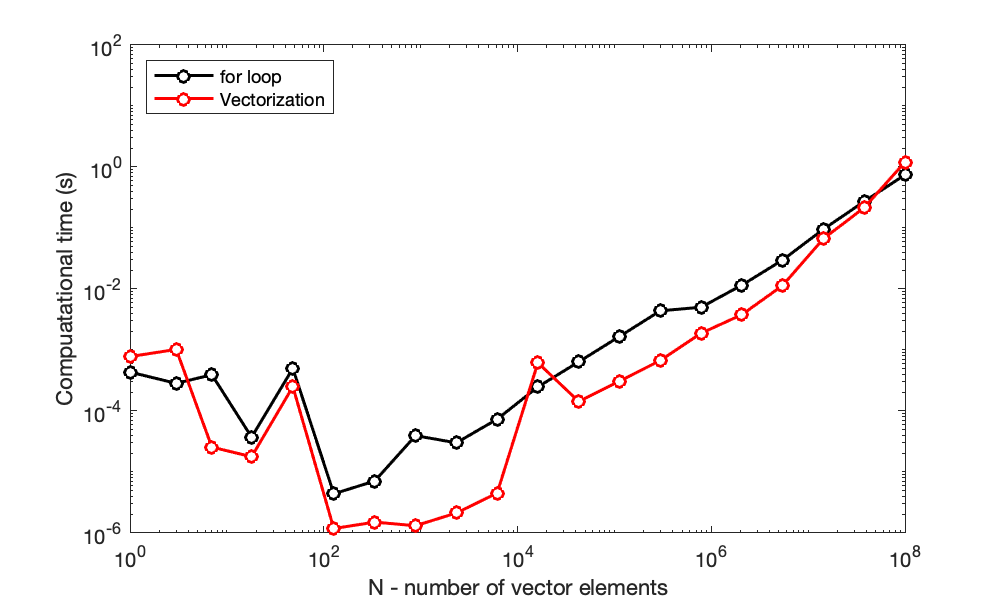

% Define dimensions of plot
figure('Position',[0,0,500,300]);
% Plot call and graphical commands
plot(N,t_for,'ko-',N,t_vec,'ro-','LineWidth',1.5,'MarkerFaceColor','auto')
set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
set(gca,'XMinorTick','on')
xlim([10^0,10^8]);
ylim([10^-6,10^2]);
xlabel('N - number of vector elements');
ylabel('Compuatational time (s)');
legend('for loop','Vectorization','Location','northwest')

**Major takeaway**: you can save an **order of magnitude** of computational time using **vectorization** rather than a for loop (even with preallocation!).

**Remember**: we want code that is correct, clear, and computationally efficient.